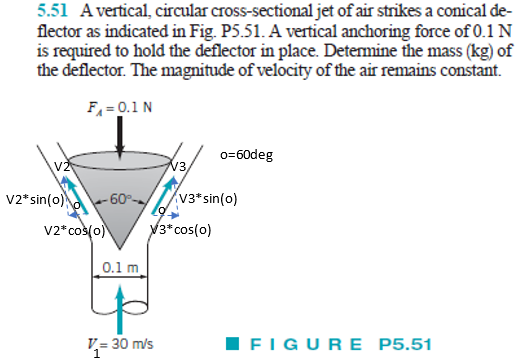

# given

u = symunit;
rho = 1.23*u.kg/u.m^3;
g = 9.81*u.m/u.s^2;
theta = 60*u.deg;
Fa = 0.1*u.N;

# inflow properties

D1 = 0.1*u.m;
A1 = sympi*D1^2/4;
V1 = 30*u.m/u.s;
V1x = 0;
V1y = 30*u.m/u.s;
mdot1 = rho*A1*V1;

# outflow properties

V2 = V1;
V2x = V2*cos(theta);
V2y = V2*sin(theta); 
V3 = V1;
V3x = V3*cos(theta);
V3y = V3*sin(theta);

# conservation of mass

syms mdot2 mdot3;
eqn = sym.zeros(3,1);
eqn(1) = mdot1 == mdot2+mdot3;

# conservation of momentum (x-direction)

eqn(2) = 0 == -mdot1*(V1x)+mdot2*(-V2x)+mdot3*(V3x);

# conservation of momentum (y-direction)

syms md;
eqn(3) = -Fa-md*g == -mdot1*(V1y)+mdot2*(V2y)+mdot3*(V3y);

# solution

eqn = simplify(eqn);
[md mdot2 mdot3] = solve(eqn, [md mdot2 mdot3]); %#ok
md = simplify(md);
md_vpa = vpa(md, 4) %#ok

$$md\_vpa = 0.1085\,\mathrm{kg}$$

clear md_vpa;